# Sample 8-3

## 離散コサイン変換

画像符号化

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete cosine transform

Image codec

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 単変量変換行列の定義

(Definition of univariate transform)

- 回転行列(rotation matrix)

            
$$\mathbf{A}_{\theta} = \left(\begin{array}{cc} \cos\theta & -\sin\theta \\ \sin\theta & \cos\theta \end{array}\right)$$


Atheta = @(theta) [cos(theta) -sin(theta) ; sin(theta) cos(theta)];

### ブロック毎の処理の定義

(Definition of patch processing)

順変換　→　量子化　→　逆量子化　→　逆変換

(Forward transform → Quantization → Inverse quantization → Inverse transform)

        
$$T(\mathbf{X})=\mathbf{A}^{-1}\left(\mathbf{Q}\odot\mathrm{round}( (\mathbf{AXA}^T)\oslash\mathbf{Q})\right)\mathbf{A}^{-T}$$


- $\odot$: 要素毎の掛け算 (Entry-wise multiplication)

- $\oslash$: 要素毎の割り算 (Entry-wise division)

mycodec = @(X,A,Q) inv(A)*(Q.*(round((A*double(X.data)*A.')./Q)))*inv(A).';

ブロックサイズ (Patch size)

blkSz = [2 2];

### 配列に対するブロック処理

品質制御パラメータ (Quality factor)

- 量子化ステップを制御 (Controls the quantization step)

Qfactor = 1;

### 入力配列の定義

 (Definition of input array)

U = [
    2 2 3 1 ;
    2 2 3 1 ;
    3 3 2 0 ;
    1 1 0 2 ];

### 単位行列の場合

 (For the indentity matrix case)

A0 = eye(blkSz) % or Atheta(0)

A0 =      1     0
     0     1


量子化テーブル (Quantization table) $\mathbf{Q}$

Q0 = Qfactor*[ % Flat
    2 2 ; 
    2 2 ];

符号化および復号(Coding and decoding)

% Definition of block processing
mycodec0 = @(x) mycodec(x,A0,Q0);

% Run codec
V0 = blockproc(U,blkSz,mycodec0)

V0 =      2     2     4     2
     2     2     4     2
     4     4     2     0
     2     2     0     2


% Error
U-V0

ans =      0     0    -1    -1
     0     0    -1    -1
    -1    -1     0     0
    -1    -1     0     0


### ハール変換の場合

 (For the Haar case)

Ah = Atheta(-pi/4)

Ah =     0.7071    0.7071
   -0.7071    0.7071


量子化テーブル (Quantization table) $\mathbf{Q}$

Qh = Qfactor*[ % Manually weighted
    3 4 ;
    4 5 ]/2;

符号化および復号(Coding and decoding)

% Definition of block processing
mycodech = @(x) mycodec(x,Ah,Qh);
% Run codec
Vh = blockproc(U,blkSz,mycodech)

Vh =     2.2500    2.2500    3.2500    1.2500
    2.2500    2.2500    3.2500    1.2500
    3.2500    3.2500    2.0000   -0.5000
    1.2500    1.2500   -0.5000    2.0000


% Error
U-Vh

ans =    -0.2500   -0.2500   -0.2500   -0.2500
   -0.2500   -0.2500   -0.2500   -0.2500
   -0.2500   -0.2500         0    0.5000
   -0.2500   -0.2500    0.5000         0


### 品質評価 

(Quality assesment) 

        $\mathrm{PSNR}(\mathbf{U},\mathbf{V}) = 10\log_{10}\frac{\mathrm{peak}^2}{\mathrm{MSE}(\mathbf{U},\mathbf{V})}$ [dB]

- PSNRが大きいほど誤差が小さい (Larger PSNR means smaller error.)

Qfactor

Qfactor = 1

fprintf('PSNR (theta=0): %6.2f [dB]',psnr(U,V0,max(U(:))))

PSNR (theta=0):  12.55 [dB]

fprintf('PSNR (theta=-π/4): %6.2f [dB]',psnr(U,Vh,max(U(:))))

PSNR (theta=-π/4):  20.61 [dB]

### 原画像の読込

(Read an image)

U = rgb2gray(imread('data/barbaraFaceRgb.tif'));

### 符号化および復号

(Coding and decoding)

単位行列の場合 (For the indentity matrix case)

% Run codec w/ θ = 0
V0 = cast(blockproc(U,blkSz,mycodec0),'like',U);

ハール変換の場合 (For the Haar case)

% Run codec w/ θ=-π/4
Vh = cast(blockproc(U,blkSz,mycodech),'like',U);

### 品質評価 

(Quality assesment) 

Qfactor

Qfactor = 1


fprintf('PSNR (theta=-π/4): %6.2f [dB]',psnr(U,Vh))

PSNR (theta=-π/4):  51.85 [dB]

### 画像表示

(Image show)

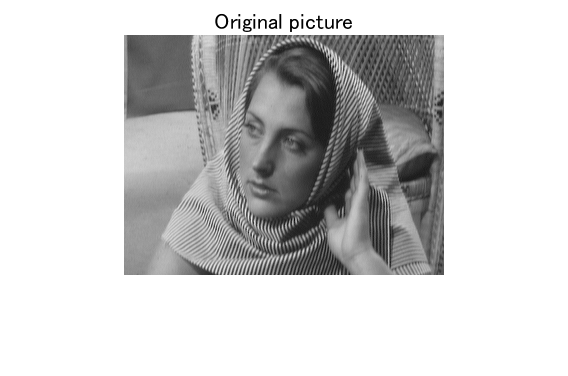

figure(1)
imshow(U)
title('Original picture')

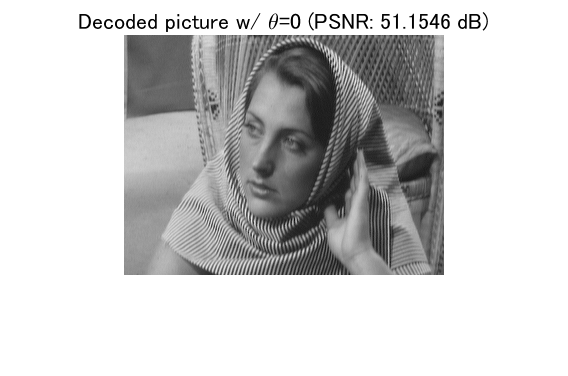

figure(2)
imshow(V0)
title(['Decoded picture w/ \theta=0 (PSNR: ' num2str(psnr(U,V0)) ' dB)'])

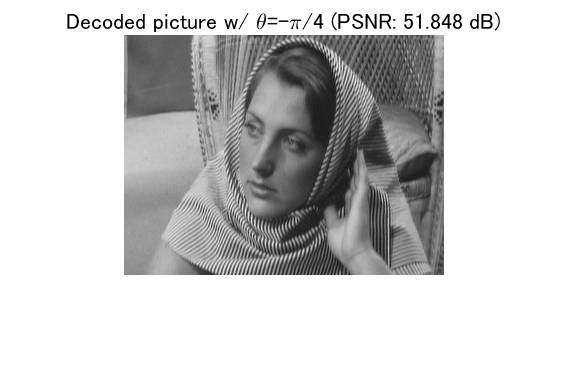

figure(3)
imshow(Vh)
title(['Decoded picture w/ \theta=-\pi/4 (PSNR: ' num2str(psnr(U,Vh)) ' dB)'])

© Copyright, Shogo MURAMATSU, All rights reserved.